 
clear
[scenario, testName] = kidneyBeanTest;
video1 = false;
video2 = false;
video3 = true;

bounds = roadBoundaries(scenario);

outerBounds = flip(bounds{1}(:,1:2),1);
innerBounds = bounds{2}(:,1:2);
centers = horzcat(mean([innerBounds(:,1), outerBounds(:,1)],2),mean([innerBounds(:,2), outerBounds(:,2)],2));

centersDiff = [0; sqrt(sum((centers(2:end,:)-centers(1:end-1,:)).^2,2))];
sVals = cumsum(centersDiff);

normFactor = floor(sVals(end))/sVals(end);

centersNormalized = centers.*normFactor;
sValsNormalized = sVals.*normFactor;

waypoints = [spline(sValsNormalized, centersNormalized(:,1),0:sValsNormalized(end))',...
             spline(sValsNormalized, centersNormalized(:,2),0:sValsNormalized(end))'];

fprintf(['Beginning Optimization' newline])

Beginning Optimization


tic
[waypointsFit, videoSet, videoSetPt, sFit] = discreteWaypointOptimizer(waypoints, normFactor*3, 50, 0.01, 0.2, testName);

Iteration: 1.000000 || k: 13.901837
Iteration: 2.000000 || k: 13.832035
Iteration: 3.000000 || k: 13.787248
Iteration: 4.000000 || k: 13.741397
Iteration: 5.000000 || k: 13.695443
Iteration: 6.000000 || k: 13.649632
Iteration: 7.000000 || k: 13.603642
Iteration: 8.000000 || k: 13.557790
Iteration: 9.000000 || k: 13.511998
Iteration: 10.000000 || k: 13.413395
Iteration: 11.000000 || k: 13.541298
Iteration: 12.000000 || k: 13.525437
Iteration: 13.000000 || k: 13.449399
Iteration: 14.000000 || k: 13.459634
Iteration: 15.000000 || k: 13.366163
Iteration: 16.000000 || k: 13.355927
Iteration: 17.000000 || k: 13.338140
Iteration: 18.000000 || k: 13.250286
Iteration: 19.000000 || k: 13.231820
Iteration: 20.000000 || k: 13.219346
Iteration: 21.000000 || k: 13.216785


t = toc;
fprintf(['Optimization Complete: %f sec' newline],t);

Optimization Complete: 69.634199 sec


Beginning Video Output By Velocity...


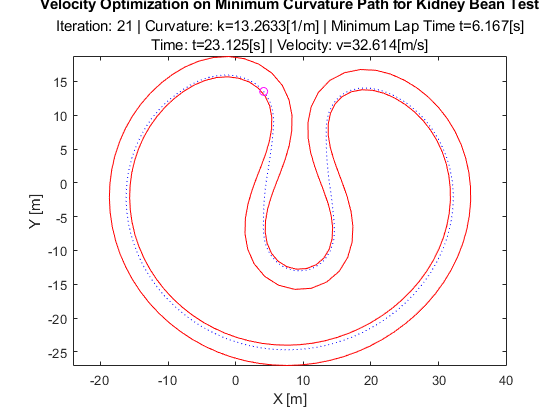

Velocity Video Complete: 173.599753 sec


videoSet(:,1) = cellfun(@(x) x/normFactor, videoSet(:,1), 'un',0);
videoSetPt(:,1) = cellfun(@(x) x/normFactor, videoSetPt(:,1), 'un',0);

videoSet(:,3) = cellfun(@(x) x/normFactor, videoSet(:,3), 'un',0);
videoSetPt(:,3) = cellfun(@(x) x/normFactor, videoSetPt(:,3), 'un',0);

waypointsFit = waypointsFit./normFactor;

[velocityProfile, minTLap] = velocityProfiler(0.001, [waypointsFit(1:end-1,:); waypointsFit(1:end-1,:); waypointsFit(:,:)], sFit, 4*300, 0.5*300, 300);
iterationEnd = videoSet{end,2};
curvatureEnd = videoSet{end,3};


if video1
    fprintf(['Beginning Video Output By Iteration...' newline]);
    tic
    writer1(videoSet, testName, centers, innerBounds, outerBounds);
    t=toc;
    fprintf(['Video 1 Complete: %f sec' newline],t);
end

if video2
    fprintf(['Beginning Video Output By Point...' newline])
    tic
    writer2(videoSetPt, testName, centers, innerBounds, outerBounds);
    t=toc;
    fprintf('Video 2 Complete: %f sec',t);
end

if video3
    fprintf(['Beginning Video Output By Velocity...' newline])
    tic
    writer3(velocityProfile, 40, testName, waypointsFit, innerBounds, outerBounds, minTLap, iterationEnd, curvatureEnd);
    t=toc;
    fprintf('Velocity Video Complete: %f sec',t);
end



if ~video1 && ~video2 && ~video3
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        waypointsFit(:,1), waypointsFit(:,2), 'm',...
        'Visible',"on");
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{end,2}),' | Curvature: k=',num2str(videoSet{end,3})]);
end

function writer1(videoSet, testName, centers, innerBounds, outerBounds)
writer = VideoWriter(testName(testName ~= ' '));
writer.FrameRate = 1;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer2(videoSet, testName, centers, innerBounds, outerBounds)
writer = VideoWriter([testName(testName ~= ' '),'ByPt']);
writer.FrameRate = 60;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    plot(videoSet{idxVidSet,4}(1), videoSet{idxVidSet,4}(2),'*m');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer3(videoSet, fps, testName, minCurPath, innerBounds, outerBounds, minTLap, itEnd, kEnd)
writer = VideoWriter([testName(testName ~= ' '),'ByVel']);
writer.FrameRate = fps;
skipFactor = (1/fps)*(1/(videoSet(2,2)-videoSet(1,2)));
open(writer);
for idxVidSet = 1:skipFactor:size(videoSet,1)
    plot(minCurPath(:,1), minCurPath(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet(idxVidSet,4), videoSet(idxVidSet,5), 'mo',...
        'Visible',"on");
    hold on
    title(['Velocity Optimization on Minimum Curvature Path for ',testName],['Iteration: ',num2str(itEnd,'%.0f'),' | Curvature: k=',num2str(kEnd),'[1/m] | Minimum Lap Time t=',num2str(minTLap,'%.3f'),'[s]', newline,'Time: t=',num2str(videoSet(idxVidSet,2),'%.3f'),'[s] | Velocity: v=',num2str(videoSet(idxVidSet,1),'%.3f'), '[m/s]']);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

% [ai] a(v=0) = 0
% [av] a(v=20) = 3
% [am] a(v=40) = 6
% da/dv = ra((am-a)/am)
% da/dt max = 2
% dv/dt max = 5
% dp/dt max = 40
% a = am/(1+be^(-kv))
% 